**Ex. 1:**

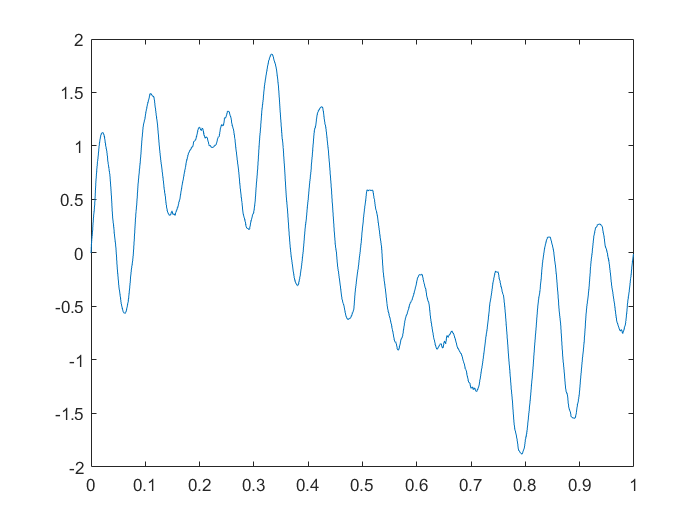

[x,t]= GeraSinalF(1000,0.001);
figure(1)
plot(t,x);

**Ex. 2:**

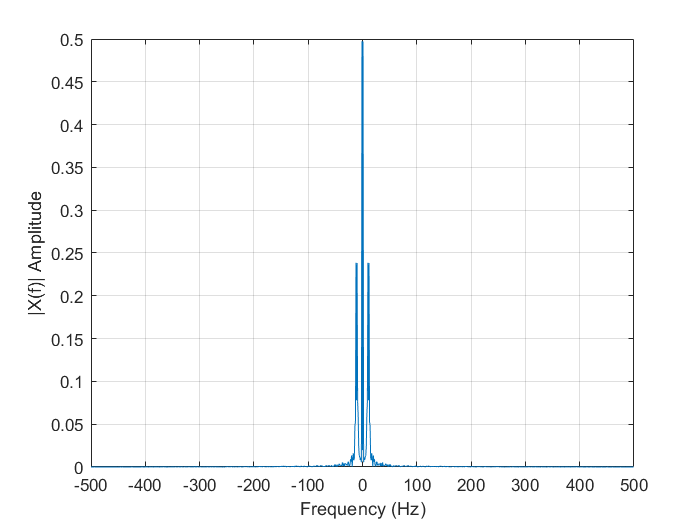

figure(2)
[X,f]=Espectro(x,0.001,0); %resulta [x,f]

**Ex. 3:**

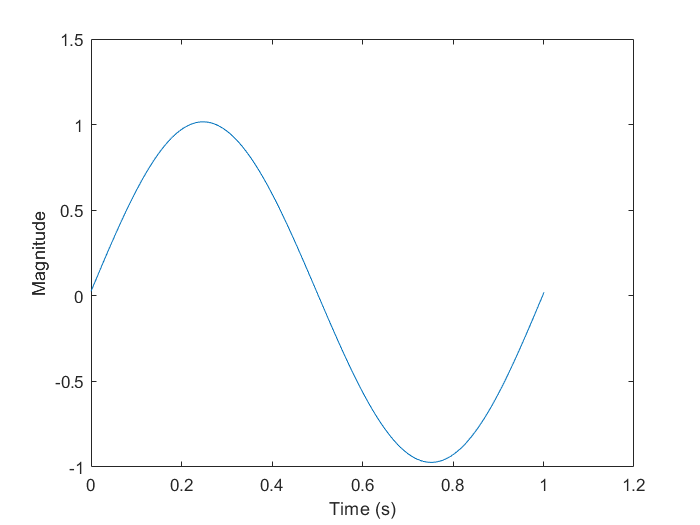

H=zeros(size(x));
fc=2;
%Fc é a frequencia que vemos visualmente, a que queremos
H(f>-fc)=1;
H(f>fc)=0;


Y=H.*X; %aplicar o filtro no domínio da freq

%Filtracao Logica


figure(3)
[y,t]= Reconstroi(Y,f);

potenciaSinal=power_signed(y)

potenciaSinal = 0.4948

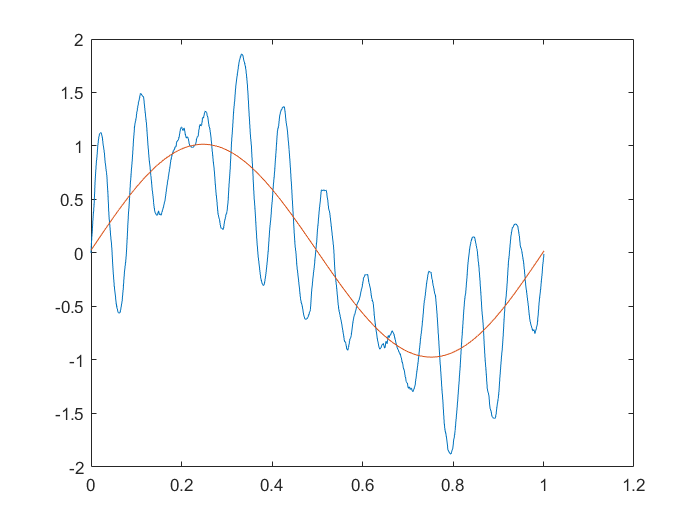

plot(t,x,t,y); %plot dos dois sinais sobrepostos, separamos sinal util e sinal com ruído.

**Ex. 4:**

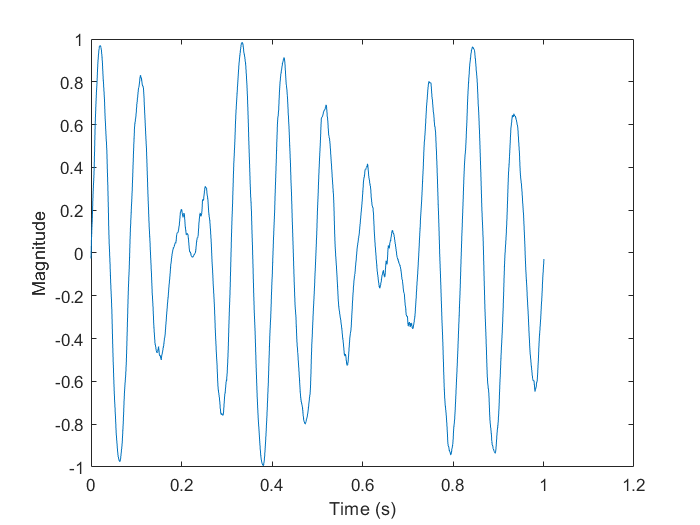

G=1-H;
Z= G.*X;
[z,t]=Reconstroi(Z,f);

potenciaRuido=power_signed(z)

potenciaRuido = 0.2736

**Ex. 5:**

Conclusão, a função geraSinal deve manter-se praticamente constante. Apesar de os sinais serem diferentes maneiras de execução para execução a potência envolvida será sempre a mesma.

relacao=potenciaSinal/potenciaRuido

relacao = 1.8083

%em Decibeis
relacaoDB= 10*log10(relacao);

fprintf('SNR= %.3f \n', relacao);

SNR= 1.808 


fprintf('SNR = %.3f db\n',relacaoDB);

SNR = 2.573 db


**Funções**

function [x,t]= GeraSinalF(N,Ta)
    t=[0: (N-1)]'*Ta;
    
    rn1=random('normal', 0,pi,N,1);
   %garantir que existem duas coisas aleatórias diferentes
    rn2=random('normal', 0,pi,N,1);
   
    %alocar memória das nossas variáveis
   phi1= zeros(N,1); %vetor de amostras do integral de rn1 e rn2
   phi2=zeros(N,1);
   
   %temos de calcular o integral de rn, aplicamos a regra do trapézio,
   %para a energia ser localizada, ainda com ruído, + suave.
   
   for k=2:N
       phi1(k)= phi1(k-1)+(rn1(k)+rn1(k-1))*Ta/2;
       phi2(k)= phi2(k-1)+(rn2(k)+rn2(k-1))*Ta/2;
   end
   %funcao recursiva
   
    r= 0.5*sin(20*pi*t+10*phi1)+0.5*sin(24*pi*t+10*phi2);

    x= sin(2*pi*t) +r;
   
end

Nota:   Se inicializassemos apenas como phi1=0, quando fose o ciclo,nao dava certo, pois o matlab vai criando memoria nova, vai sempre criando mais espaço na memória e copia, sem necessidade nenhuma.Vai criando e apagando, é má prática de programação. Demora mais tempo,  o processador fica afetado

    function [X, f] = Espectro (x, Ta, w) 
     N= length(x);
     f0= 1/( N*Ta); %periodo= N*Ta
     fa=1/Ta;
     f=[-fa/2:fa/N:(fa/2-fa/N)]';
     
    
    %windowing
     if w~=0
        w=blackman(N);
        x=x*w;
    end
     
      
    X=fft(x);
    X=fftshift(X)/N;
     %vetor de N elementos
     
     
     plot( f, abs(X));
     xlabel('Frequency (Hz)');
     ylabel('|X(f)| Amplitude');
     grid;
     
    end
    
    
    function[x,t]= Reconstroi (X,f)
     N=length(X);
     fa=-f(1)*2;
     X = ifftshift(X);
    
     x = real( ifft(X)*N);
 
     fa = f(end)*2;
     Ta = 1/fa;
   
     t = [0: Ta: (N-1)*Ta]';
     plot(t, x);
     xlabel("Time (s)")
     ylabel("Magnitude")
    end
   

function potencia = power_signed(x)
     potencia = sum(x .^ 2) / length(x);
end